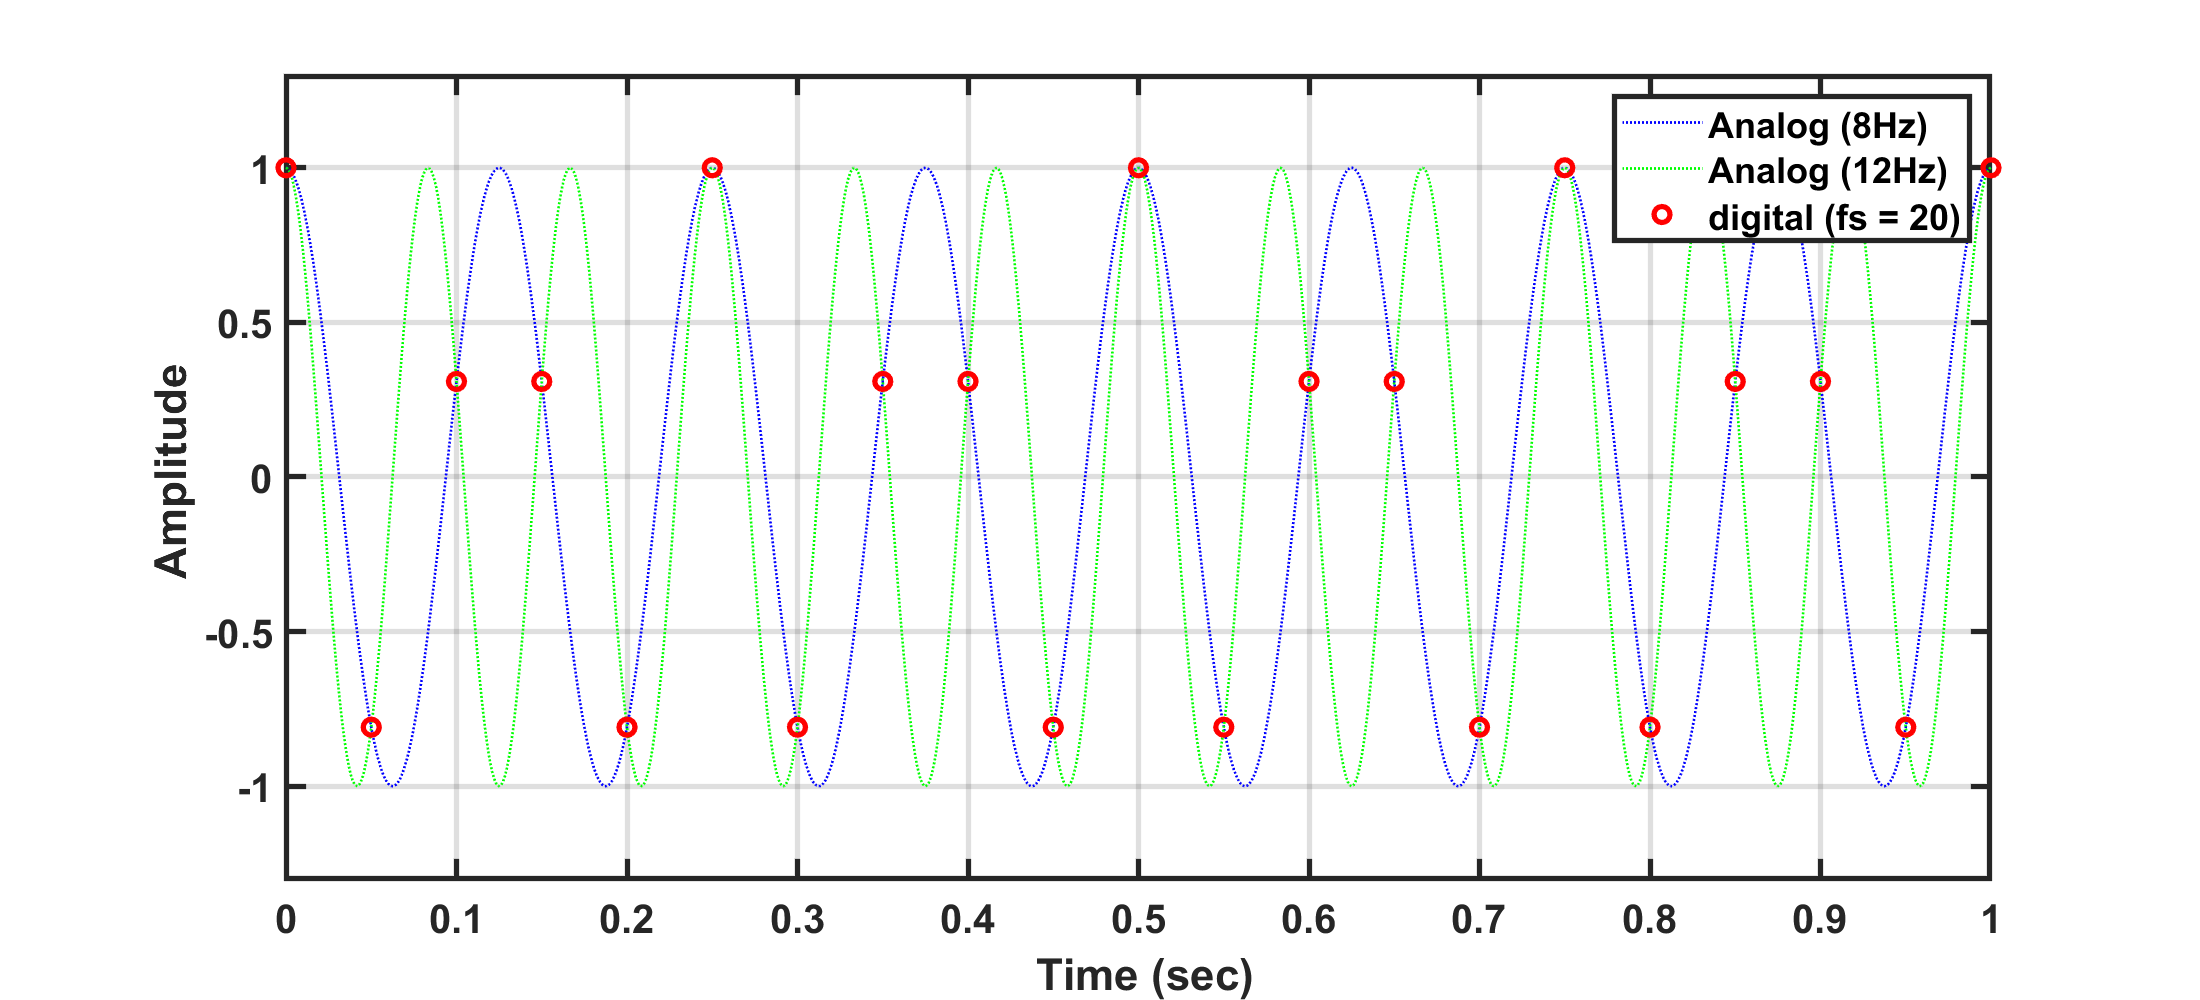

clear; clc ; close all;

syms t   

f = 8;
y = cos(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
endt = 1;
Fsa = 1000; % # of samples per a second
ta = 0:1/Fsa:endt;
ya = subs(y, t, ta);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 500]);

Fsd = 20; % # of samples per a second
td = 0:1/Fsd:endt;
yd = subs(y, t, td);

f = 12;
y2 = cos(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
Fsa = 1000; % # of samples per a second
ta2 = 0:1/Fsa:endt;
ya2 = subs(y2, t, ta2);

plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(ta2, ya2, ':g','linewidth', 1)
plot(td,yd,'or','linewidth',2); hold off;
legend('Analog (8Hz)', 'Analog (12Hz)', 'digital (fs = 20)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

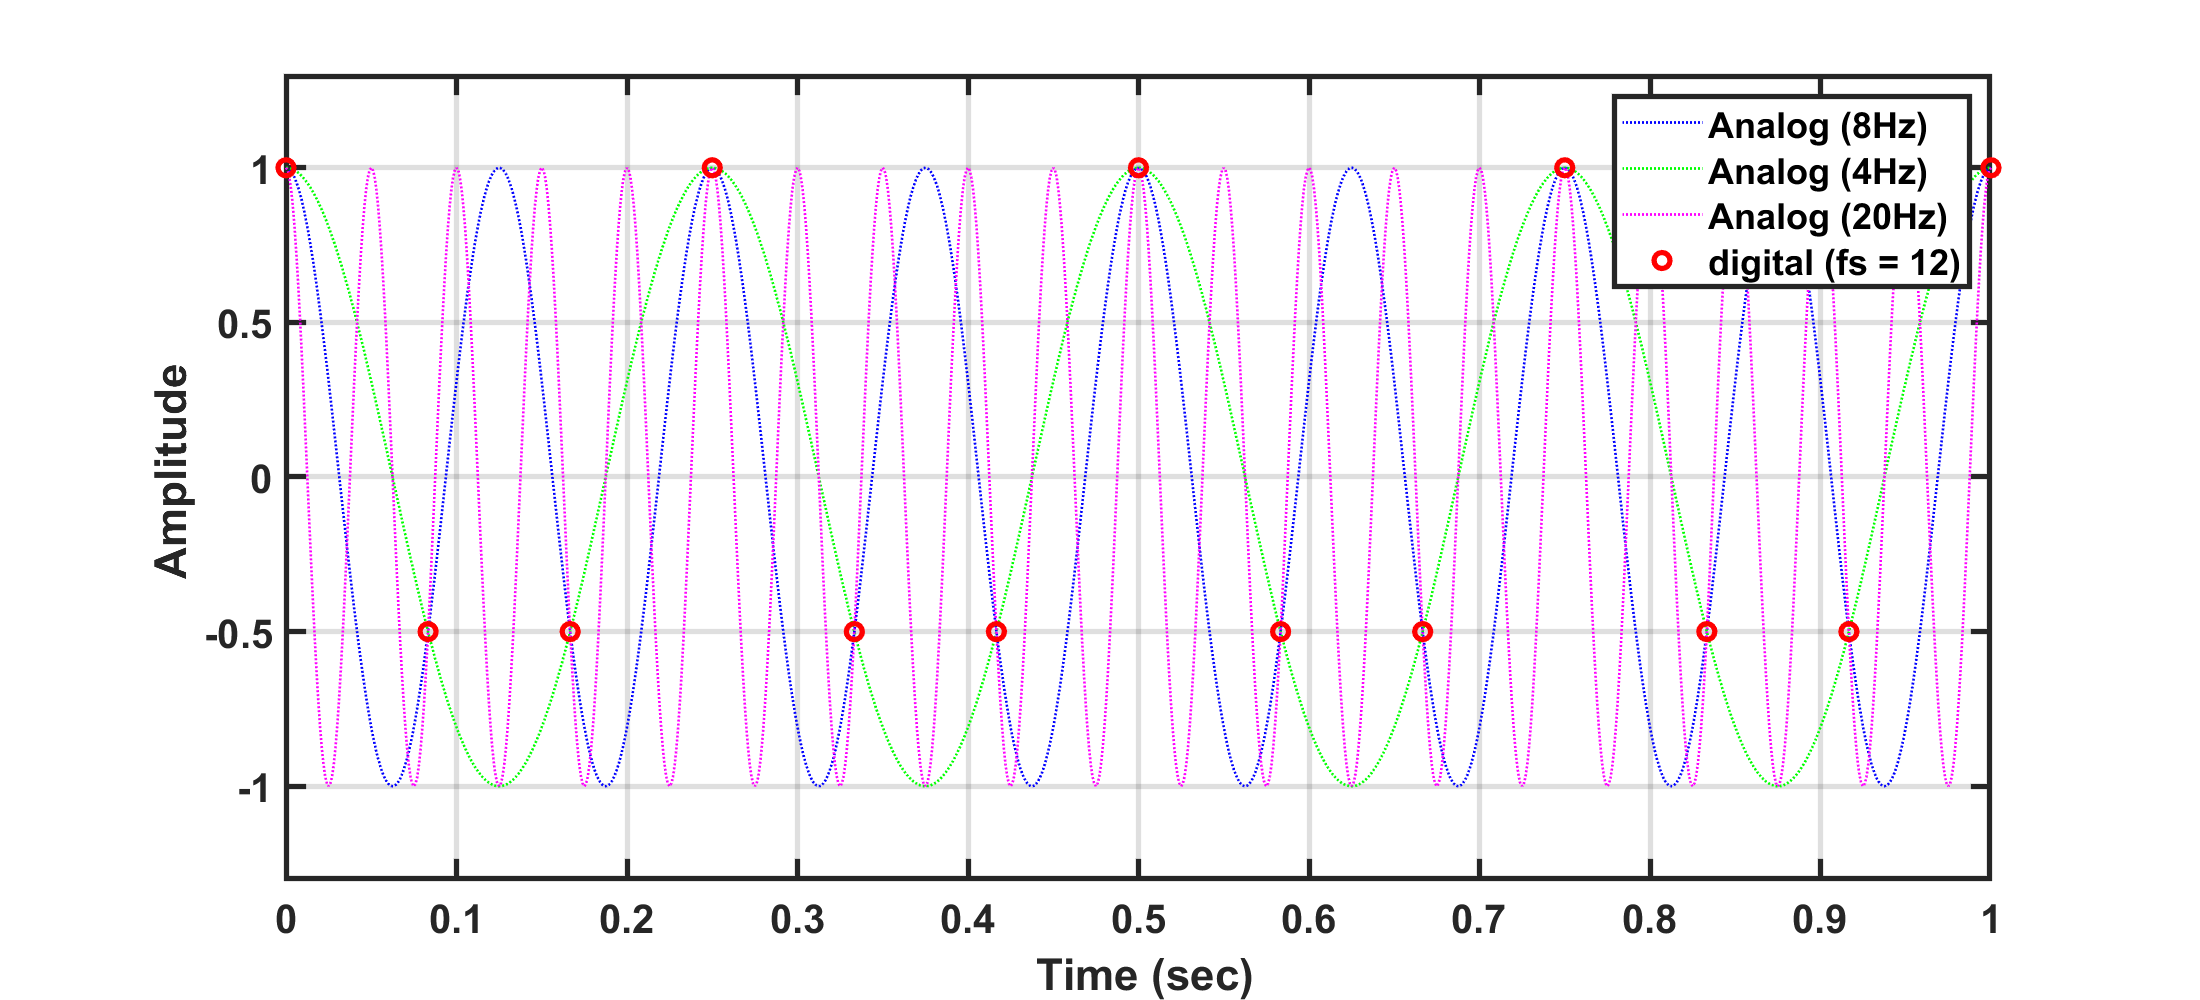

clear; clc ; close all;

syms t   

f = 8;
y = cos(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
endt = 1;
Fsa = 1000; % # of samples per a second
ta = 0:1/Fsa:endt;
ya = subs(y, t, ta);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 500]);

Fsd = 12; % # of samples per a second
td = 0:1/Fsd:endt;
yd = subs(y, t, td);

f = 4;
y2 = cos(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
Fsa = 1000; % # of samples per a second
ta2 = 0:1/Fsa:endt;
ya2 = subs(y2, t, ta2);

f = 20;
y3 = cos(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
Fsa = 1000; % # of samples per a second
ta3 = 0:1/Fsa:endt;
ya3 = subs(y3, t, ta3);

plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(ta2, ya2, ':g','linewidth', 1)
plot(ta3, ya3, ':m','linewidth', 1)
plot(td,yd,'or','linewidth',2); hold off;
legend('Analog (8Hz)', 'Analog (4Hz)','Analog (20Hz)', 'digital (fs = 12)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')